% =========================================================================
% 2. NEURÁLIS HÁLÓ (Zaj-becslő / Sigma háló) TANÍTÁSA
% =========================================================================
disp('=== 2. Neurális Háló (Zaj-becslő / Sigma) Tanítása Indul ===');

=== 2. Neurális Háló (Zaj-becslő / Sigma) Tanítása Indul ===


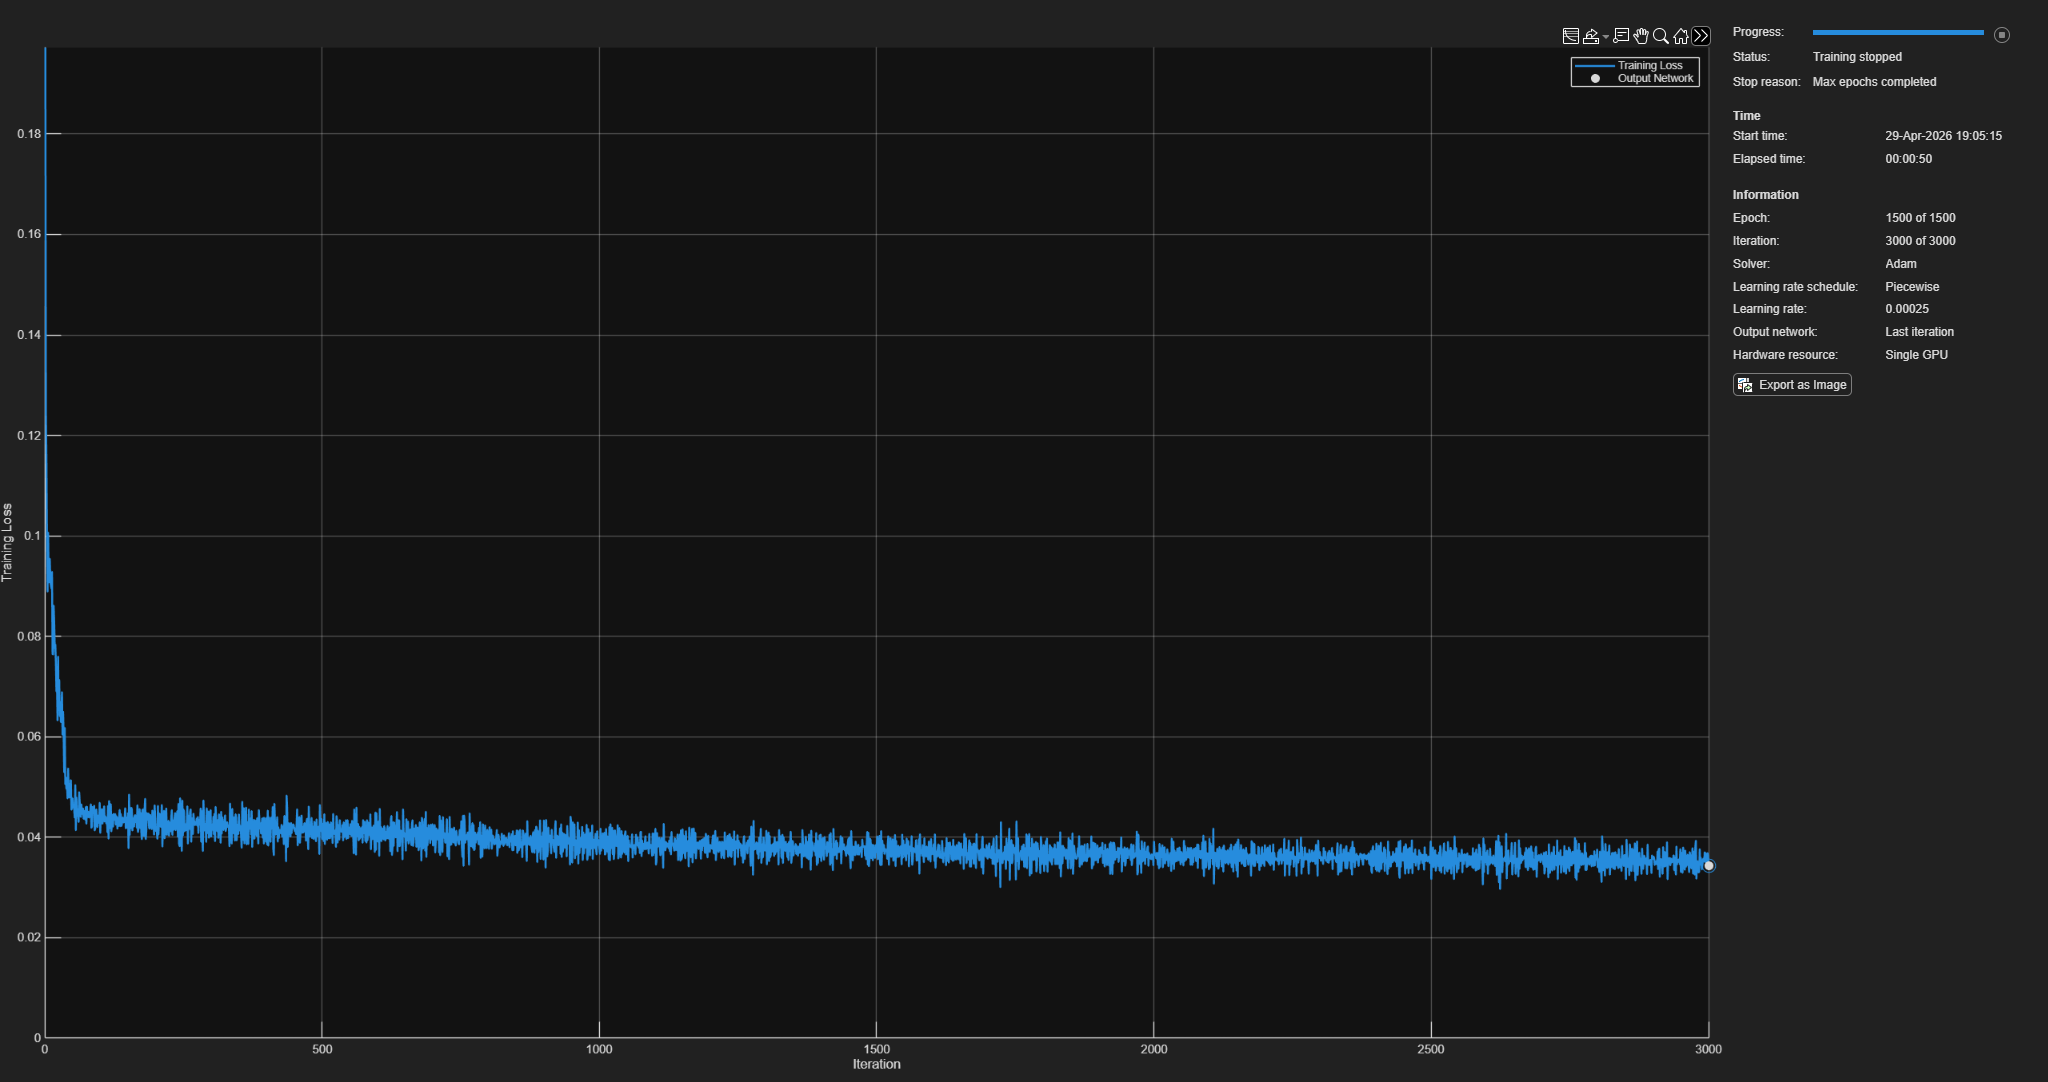


% Ellenőrzés: Megvan-e az első háló (A Fizikus)
if ~exist('net', 'var')
    error('Hiba: Nem találom az 1. hálót ("net")! Előbb azt kell betanítani.');
end

% --- 1. A ZAJ (CÉLADAT) ELŐÁLLÍTÁSA ---
% Az összes tanító bemenetet lefuttatjuk a már kész 1. hálón (mu)
X_all_dl = dlarray(Training_Inputs', 'CB');
Y_pred_mu = extractdata(predict(net, X_all_dl))';

% Kiszámoljuk az eltérést a valóság és az 1. háló jóslata között
% Ez a nyers zaj (ami hol pozitív, hol negatív, a szélhullámok miatt)
nyers_zaj = Training_Outputs - Y_pred_mu;

% A 2. háló (sigma) célja ennek a zajnak a MÉRTÉKÉT megtanulni.
% Ezért abszolút értéket vonunk belőle (a szórás nem lehet negatív!)
Training_Outputs_Sigma = abs(nyers_zaj);

% --- 2. ADATOK FELCÍMKÉZÉSE ---
XTrain_dl_sigma = dlarray(Training_Inputs', 'CB');
YTrain_dl_sigma = dlarray(Training_Outputs_Sigma', 'CB');

% --- 3. HÁLÓZAT ARCHITEKTÚRÁJA ---
layers_sigma = [
    featureInputLayer(6, 'Normalization', 'zscore', 'Name', 'input') 

    fullyConnectedLayer(64, 'Name', 'fc_1')  % Kicsit kisebb, mint az 1. háló
    tanhLayer('Name', 'tanh_1')             

    fullyConnectedLayer(32, 'Name', 'fc_2')  
    tanhLayer('Name', 'tanh_2')

    fullyConnectedLayer(16, 'Name', 'fc_3')  
    tanhLayer('Name', 'tanh_3')

    fullyConnectedLayer(4, 'Name', 'output') % 4 kimenet (a 4 állapot bizonytalansága)

    % ÚJ: Mivel a zaj mértéke sosem lehet negatív, levágjuk a negatív számokat!
    reluLayer('Name', 'relu_out')
    ];

% --- 4. TANÍTÁSI PARAMÉTEREK (Finomhangolva sztochasztikus zajhoz) ---
options_sigma = trainingOptions('adam', ...
    'MaxEpochs', 1500, ...                 % Megemeljük, mert lassabban fog tanulni
    'MiniBatchSize', 256, ...              % JAVÍTÁS: Sokkal nagyobb adagok -> simább gradiens!
    'InitialLearnRate', 0.002, ...         % JAVÍTÁS: Kisebb kezdő lépésköz
    'L2Regularization', 1e-4, ...          % ÚJ: Szigorítjuk, hogy ne próbálja "bemagolni" a zajt
    'LearnRateSchedule', 'piecewise', ... 
    'LearnRateDropPeriod', 400, ...        % Később kezdjük el lassítani
    'LearnRateDropFactor', 0.5, ...       
    'Shuffle', 'every-epoch', ...       
    'Plots', 'training-progress', ...   
    'Verbose', false);

% --- 5. HÁLÓZAT TANÍTÁSA ---
net_sigma = trainnet(XTrain_dl_sigma, YTrain_dl_sigma, layers_sigma, "mse", options_sigma);


disp('=== TANÍTÁS BEFEJEZŐDÖTT! A "net_sigma" nevű objektum elkészült. ===');

=== TANÍTÁS BEFEJEZŐDÖTT! A "net_sigma" nevű objektum elkészült. ===



% -------------------------------------------------------------------------
% 6. GYORS TESZT
% -------------------------------------------------------------------------
disp('--- Tesztelés az első időlépésen ---');

--- Tesztelés az első időlépésen ---


teszt_bemenet = dlarray(Training_Inputs(1, :)', 'CB'); 

becsult_zaj_mertek = predict(net_sigma, teszt_bemenet);

disp('Valós zaj mértéke (abszolút hiba az 1. hálónál) az adott pontban:');

Valós zaj mértéke (abszolút hiba az 1. hálónál) az adott pontban:


disp(Training_Outputs_Sigma(1, :));

    0.0000    0.0000    1.0235    0.1585




disp('A 2. háló (Zaj-becslő) által jósolt bizonytalanság (sigma):');

A 2. háló (Zaj-becslő) által jósolt bizonytalanság (sigma):


disp(extractdata(becsult_zaj_mertek)');

         0         0    0.5150    0.1531

